clear all; close all;

filename = 'MYD13Q1.061_250m_aid0001_(2000-2021).nc';
ndvi = ncread(filename, '_250m_16_days_NDVI');
A = ~isnan(ndvi(:,:, 15)); % A is a matrix which has the value 1 for
                           % the area we are interested in
[nr, nc, ~] = size(ndvi);
final_matrix = [];
for t = 1:449
    x = ndvi(:,:, t);
    new_col = x(A(:,:));
    new_col = new_col(:);
    final_matrix = [final_matrix new_col];
end
clear t; clear new_col; clear x;

lats = ncread(filename, 'lat');
lons = ncread(filename, 'lon');
%lons = vertcat(zeros(1,1), lons(1:end,:));

lats_all = [];
lons_all = [];
for col = 1:nc
    for row = 1:nr
        if A(row, col) == 1
            lats_all = [lats_all lats(col)];
            lons_all = [lons_all lons(row)];
        end
    end
end
lats_all = lats_all';
lons_all = lons_all';
clear col; clear row; clear A;    

% fetching the time in one row vector
time = ncread(filename, 'time')';
[~,nt] = size(time);
startdate = datetime(2000,1,1);
dates = startdate + days(time);
years =[];
months = [];
for day = dates
    [y,m,~]=ymd(day);
    years = [years y];
    months = [months m];
end
clear y; clear startdate; clear day; clear m; clear time;
final_matrix=[years; final_matrix]; 

final_years = []; % each column has the maximum value for that year, 
month_maxndvi = [];
% each row has pixel from the outer part of the delta
for y = 2002:2021
    ndvi_y = [];
    month_y = [];
    for t = 1:nt  % nt is number of images
        if final_matrix(1, t) == y
            ndvi_y = [ndvi_y final_matrix(:, t)];
            month_y = [month_y months(t)];
        end
    end
    % now take the maximum for that year
    final_years = [final_years max(ndvi_y, [], 2)];
    [~, indx] = max(ndvi_y(2:end, :), [], 2);
    month_maxndvi_col = [];
    for i = 1:size(indx)
        month_maxndvi_col = [month_maxndvi_col month_y(indx(i))];
    end
    clear i;
    month_maxndvi = [month_maxndvi month_maxndvi_col'];
end
clear y; clear t; clear ndvi_y;   clear month_y; clear indx; clear month_maxndvi_col;
clear years; clear months; %clear dates;
month_maxndvi = [2002:2021 ; month_maxndvi];

### Converting Matrix to Table and taking the mean of every row

T = array2table(final_years(2:end, :));
for i = 1:20 % because 20 years
    T.Properties.VariableNames{i} = num2str(2001 + i);
end
clear i;          

T.Means = mean(T{:,:},2);
T.Median = median(T{:,:},2);
[n_pixels,~] = size(final_matrix(2:end,:));

maximum = [];
for i = 1:n_pixels
    maximum = [maximum max(T{i,1:20})];
end
maximum = maximum';
T.('maximum') = maximum;
clear i; clear maximum;

T.('Latitude') = lats_all;
T.('Longitudes') = lons_all;
%clear lats_all; clear lons_all;
T = movevars(T, 24, 'Before', 1);
T = movevars(T, 25, 'Before', 2);

# Plotting

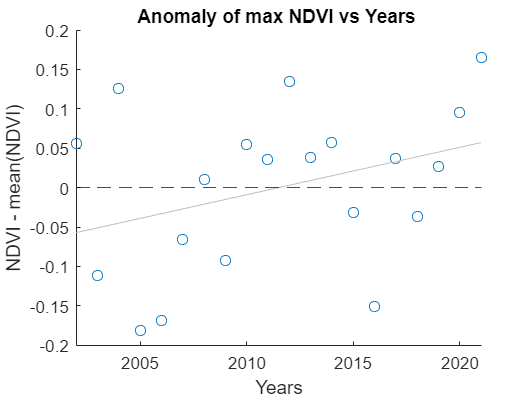

slopes = [];
for i = 1:n_pixels
    scatter(2002:2021, T{i,3:22} - T{i,23})
    xlabel('Years'); ylabel('NDVI - mean(NDVI)'); 
    title(['Anomaly of max NDVI vs Years ']);
    xlim([2002, 2021]); %ylim([-0.25, 0.45]);
    hl = lsline;
    B = [ones(size(hl.XData(:))), hl.XData(:)]\hl.YData(:);
    slopes = [slopes B(2)];
end
clear i;
slopes = slopes';
T.('trend_slopes') = slopes;
yline(0,'k--');

clear hl; clear B; clear slopes;


## Taking the top 25% slopes into a table and plotting the anomalies over 20 years

max_slope = max(T.trend_slopes);
min_slope = min(T.trend_slopes);
% taking top 25% slope
A = T.trend_slopes >= max_slope - (max_slope - min_slope)./4;
T2 = [];
for i=1:26
    T2 = [T2 T{:,i}(A)];
end
clear i; clear max_slope; clear min_slope; clear A;

T2 = array2table(T2);
T2 = renamevars(T2,T2.Properties.VariableNames, T.Properties.VariableNames);

### ***Now Plotting the anomaly***

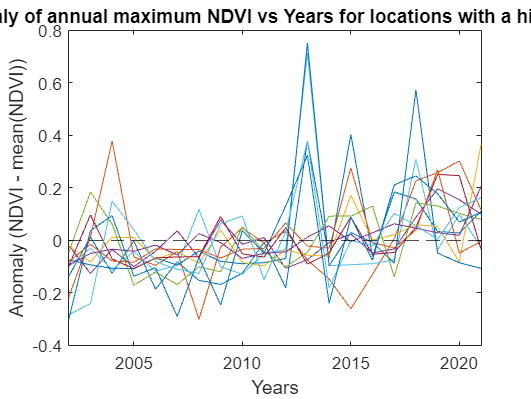

[T2nr,T2nc] = size(T2);
for i = 1:T2nr
    plot(2002:2021, T2{i,3:22} - T2{i,23})
    xlabel('Years'); ylabel('Anomaly (NDVI - mean(NDVI))'); 
    title(['Anomaly of annual maximum NDVI vs Years for locations with a high slope']);
    xlim([2002, 2021]); %ylim([-0.25, 0.45]);
    hold on
end
clear i;
yline(0,'k--');
hold off 
clear T2nr; clear T2nc
saveas(gcf,'Published_Plots\Annual-max-NDVI_anomaly_for_top25percent_slopes.pdf')

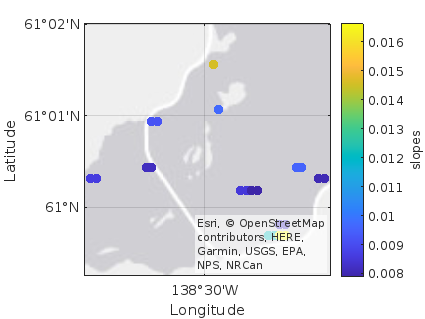

geoscatter(T2{:,1}, T2{:,2}, 50, T2{:,26},  "filled")
c4 = colorbar;
c4.Label.String = 'slopes';


clear c4;

**Converting Slopes in a 51x22 matrix**

slopes = T.('trend_slopes');
A = ~isnan(ndvi(:,:, 15));
Z_slopes = [];
x = 0;
for i = 1:nc
    z_slopes_col = [];
    indx = find(A(:,i)>0);
    start_indx = indx(1);
    end_indx = indx(end);
    z_slopes_col(1:start_indx-1) = NaN;
    z_slopes_col(indx)=slopes(x+1: x+length(indx));
    z_slopes_col(end_indx+1:nr) = missing;
    x = x+length(indx);
    Z_slopes = [Z_slopes z_slopes_col'];
end
clear A; clear end_indx; clear start_indx; clear i; 
clear x; clear z_slopes_col; clear slopes; clear indx

**surf() function**

[Y,X]=meshgrid(lats,lons);
s= surf(X,Y,Z_slopes);
s.EdgeColor = 'none'

s =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [49×19 double]
           YData: [49×19 double]
           ZData: [49×19 double]
           CData: [49×19 double]

  Show all properties


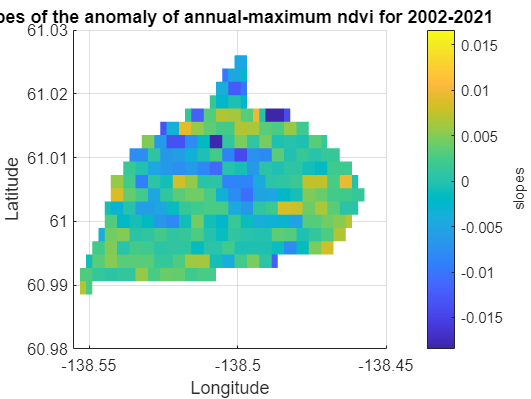

view(2);
c = colorbar;
c.Label.String = 'slopes';
xlabel("Longitude"); ylabel("Latitude");
title("Slopes of the anomaly of annual-maximum ndvi for 2002-2021")


clear c; clear s

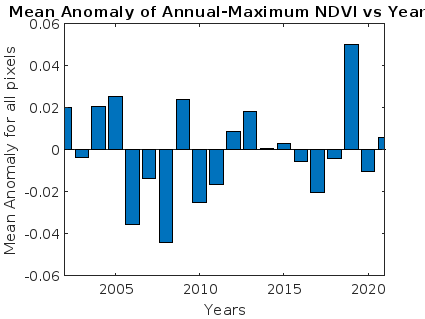

bar(2002:2021, mean(T{:,3:22} - T{:,23}))
xlabel('Years', 'FontName', 'Dialog'); 
ylabel('Mean Anomaly for all pixels', 'FontName', 'Dialog'); 
title('Mean Anomaly of Annual-Maximum NDVI vs Years ', 'FontName', 'Dialog');
xlim([2002, 2021]); %ylim([-0.25, 0.45]);
hold on

yline(0,'k--');
hold off
saveas(gcf,'Published_Plots\Mean_anomaly_of_Annual_max_NDVI.pdf')

save('Entire_region.mat')